# Linear Control Design II - Group Work Problem Module 11 Solution

## Description

The airplane model is to be extended by adding a second input: The aileron angle $\delta_a$ as shown on figure 1. The roll angle$\varphi$ is also added to the output vector. 

  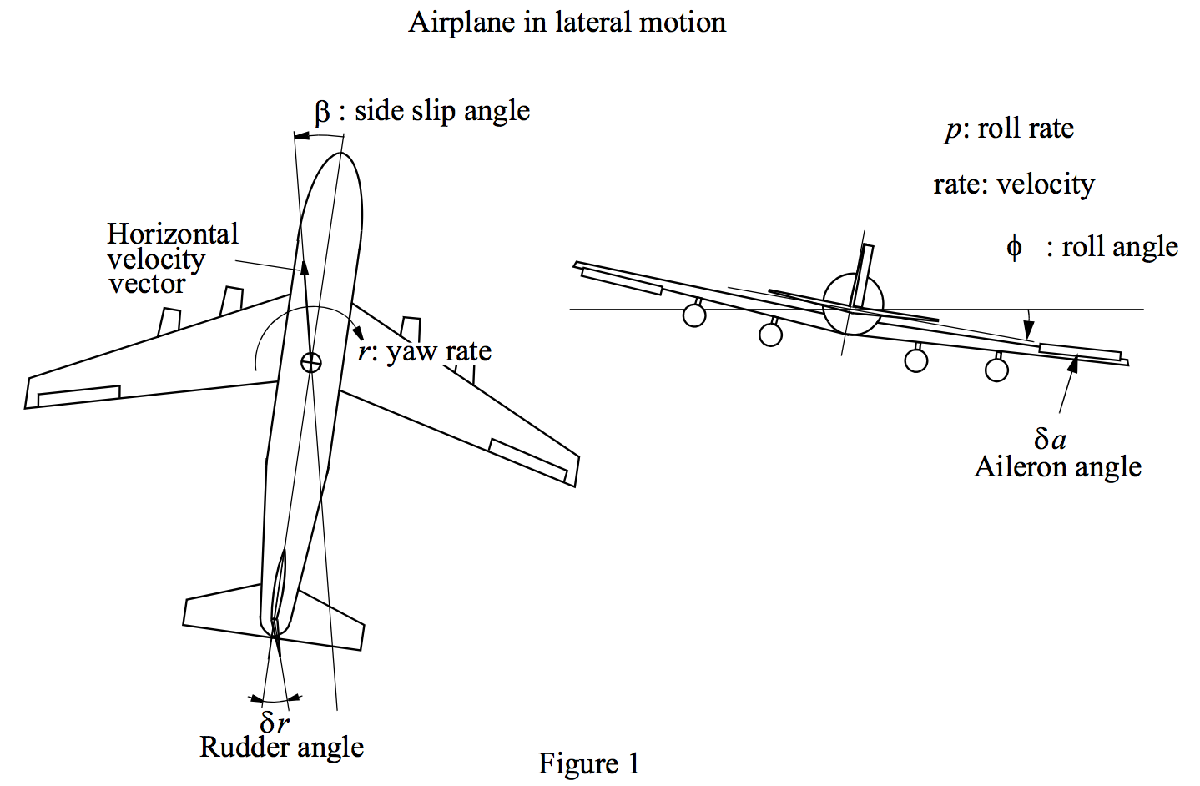

A linearized state space model of the lateral dynamics of a Boeing 747 in altitude 40000 ft and speed 774 ft/sec (850 km/h) is shown below:


$$\pmatrix{ \dot{\beta} \cr \dot{r} \cr \dot{p} \cr \dot{\varphi} } = \pmatrix{ -0.0558 &\ -0.9968 &\ 0.0802 &\ 0.0415 \cr 0.5980 &\ -0.1150 &\ -0.0318 &\ 0 \cr -3.0500 &\ 0.3880 &\ -0.4650 &\ 0 \cr 0 &\ 0.0805 &\ 1 &\ 0 } \pmatrix{ \beta \cr r \cr p \cr \varphi } + \pmatrix{ 0.00729 &\ 10^{-5} \cr -0.47500 &\ 0.123\cr 0.15300 &\ 1.063\cr 0 &\ 0} \pmatrix{ \delta r \cr \delta a }$$

$$y = \pmatrix{ 0 \ 1 \ 0 \ 0 \cr 0 \ 0 \ 0 \ 1 } \pmatrix{ \beta \cr r \cr p \cr \varphi}$$


where $\beta$ is the side-slip angle (rad), $r$is the yaw rate (rad/s), $p$ is the roll rate (rad/s), $\varphi$ is the roll angle (rad), $\delta_r$ is the rudder deflection (rad) and $\delta_a$ is the aileron angle (rad).

format short g; clear all; close all; clc;

% Define system matrices:
A = [-0.0558 -0.9968  0.0802  0.0415;
      0.598  -0.115  -0.0318  0;
     -3.050   0.388  -0.4650  0;
      0       0.0805  1       0];
B = [0.00729   1e-5; 
    -0.475     0.123; 
     0.153     1.063;     
     0         0];
C = [0 1 0 0;
     0 0 0 1];
D = zeros(2,2);

% Define state-space system:
sys_ss = ss(A,B,C,D)


sys_ss =
 
  A = 
            x1       x2       x3       x4
   x1  -0.0558  -0.9968   0.0802   0.0415
   x2    0.598   -0.115  -0.0318        0
   x3    -3.05    0.388   -0.465        0
   x4        0   0.0805        1        0
 
  B = 
            u1       u2
   x1  0.00729    1e-05
   x2   -0.475    0.123
   x3    0.153    1.063
   x4        0        0
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
   y2   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



**Problem 1  **Is the system controllable and observable?

*Use the controllability and observability matrices *$\mathbf{M}_c$* and *$\mathbf{M}_o$* (Matlab functions: *$\mathtt{ctrb}$* and *$\mathtt{obsv}$*). How would you test whether *$\mathbf{M}_c$* has 4 linearly independent columns?*

*Also use the test with the left and the right eigenvectors (first part of PBH-test, i.e. the criteria ****CC3**** and ****OC3****) and the diagonal test (****CC4**** and ****OC4****).*

**Solution****:**

First the controllability of the system will be tested and then the observability of the system will be tested.

**--- Controllability Theorem CC2:**

To test for controllability we need to evaluate if the controllability matrix Mc has full row rank. The $\mathbf{M}_c$ matrix can be written from Eq. (3.230) in the textbook with $n = 4$ (dimension of the state space); 


$$\mathbf{M}_c = \pmatrix{\mathbf{B} & \mathbf{AB} & \mathbf{A}^2\mathbf{B} & \mathbf{A}^3\mathbf{B}}$$


% Mc = [B A*B A^2*B A^3*B] is calculated by:
Mc = ctrb(A,B)

Mc =       0.00729        1e-05      0.48534    -0.037354    -0.098535     0.058581     -0.40443    0.0049517
       -0.475        0.123     0.054119    -0.047942      0.29284   -0.0026226    -0.050301     0.025698
        0.153        1.063     -0.27768      -0.4466      -1.3302        0.303       1.0327     -0.32059
            0            0      0.11476       1.0729     -0.27332     -0.45046      -1.3066      0.30279


% Test if the controlabillity matrix has at least as many 
% linearly independant columns as the number of states in the system:
if rank(Mc) >= size(A,1)
    disp('System is controllable!');
else
    disp('System is NOT controllable!');
end

System is controllable!


The rank of the $\mathbf{M}_c$ matrix is 4, so it has full row rank and the system is therefore controllable. We can also convince ourselves that the system is controllable by checking the validity of conditions **CC3** and **CC4**. 

**--- Controllability Theorem CC3 - Part 1:**

First the left eigenvectors are computed with `eig()`as 

[V,Dr,W] = eig(A); % or [W,D] = eig(A');
% V : Right eigenvectors, D : eigenvalues, W : Left eigenvectors

disp('Left eigenvectors:'); W

Left eigenvectors:


W =     -0.088261 +    0.67683i    -0.088261 -    0.67683i     -0.47231 +          0i    -0.021083 +          0i
      0.72641 +          0i      0.72641 +          0i     -0.84616 +          0i      0.97392 +          0i
    -0.066988 -   0.032468i    -0.066988 +   0.032468i     -0.24439 +          0i      0.19129 +          0i
    -0.029501 -  0.0048956i    -0.029501 +  0.0048956i     0.034837 +          0i      0.12022 +          0i

If the system has no left eigenvectors such that $w_i^\mathrm{T} \mathbf{B} = 0$ (Eq. (3.247) in the textbook) then the system is controllable. If we apply this condition to our system we obtain:


$$\mathbf{W}^T\mathbf{B} = \pmatrix{ 0.3559-0.0000i &\ -0.0181-0.0345i \cr 0.3559+0.0000i &\ -0.0181+0.0345i \cr -0.3611 &\ 0.3639 \cr -0.4335 &\ 0.3231 }$$


disp('transpose(W)*B = '); 

transpose(W)*B = 


disp(W'*B);

     -0.35594 + 3.3539e-05i     0.018139 +   0.034507i
     -0.35594 - 3.3539e-05i     0.018139 -   0.034507i
      0.36109 +          0i     -0.36387 +          0i
      -0.4335 +          0i      0.32313 +          0i


therefore, since none of the elements are zero, the first part of **CC3** indicates that the system is controllable.

**--- Controllability Theorem CC4:**

The theorem holds for systems in diagonal form, so the first step is to find the modal matrix $\mathbf{M}$, which can be used to diagonalize the system at hand. The modal matrix is


$$\mathbf{M} = \pmatrix{ 0.1994-0.1063i &\ 0.1994+0.1063i &\ -0.0172 &\ 0.0067 \cr -0.0780-0.1333i &\ -0.0780+0.1333i &\ -0.0118 &\ 0.0404 \cr -0.0165+0.6668i &\ -0.0165-0.6668i &\ -0.4895 &\ -0.0105 \cr 0.6930 &\ 0.6930 &\ 0.8717 &\ 0.9991 }$$


% The modal matrix is the same as the normal (left) eigenvector matrix. 
[M,Dr] = eig(A); M

M =       0.19937 -    0.10627i      0.19937 +    0.10627i    -0.017178 +          0i    0.0067218 +          0i
    -0.077977 -    0.13326i    -0.077977 +    0.13326i    -0.011828 +          0i     0.040422 +          0i
    -0.016547 +    0.66677i    -0.016547 -    0.66677i     -0.48953 +          0i    -0.010525 +          0i
      0.69301 +          0i      0.69301 +          0i      0.87174 +          0i       0.9991 +          0i

The transformed $\mathbf{B}_t$matrix is then 


$$\mathbf{B}_t = \mathbf{M}^{-1}\mathbf{B}$$


Bt = M\B % equivalent to inv(M)*B

Bt =       0.63546 -    0.89716i     -0.11936 -   0.015897i
      0.63546 +    0.89716i     -0.11936 +   0.015897i
       2.1477 + 1.7807e-16i      -2.1643 - 7.1086e-17i
      -2.7555 - 4.9356e-16i       2.0539 + 2.9207e-16i

It is clear that the $\mathbf{B}_t$matrix does not have zero rows, hence the **CC4** test confirms that the system is controllable.

**--- Observability Theorem OC2:**

The observability matrix $\mathbf{M}_o$ is written as in Eq. (3.301) in the textbook with $n = 4$.


$$\mathbf{M}_o = \pmatrix{ 0 &\ 1.0000 &\ 0 &\ 0 \cr 0 &\ 0 &\ 0 &\ 1.0000 \cr 0.5980 &\ -0.1150 &\ -0.0318 &\ 0 \cr 0 &\ 0.0805 &\ 1.0000 &\ 0 \cr -0.0051 &\ -0.5952 &\ 0.0664 &\ 0.0248 \cr -3.0019 &\ 0.3787 &\ -0.4676 &\ 0 \cr -0.5582 &\ 0.1013 &\ 0.0125 &\ -0.0002 \cr 1.8200 &\ 2.7673 &\ -0.0354 &\ -0.1246}$$


The rank of the observability matrix is 4, and so it has full column rank and the system is therefore observable. In MatLab this can be computed as follows:

% Calculate observability matrix:
Mo = obsv(A,C)

Mo =             0            1            0            0
            0            0            0            1
        0.598       -0.115      -0.0318            0
            0       0.0805            1            0
   -0.0051484      -0.5952     0.066404     0.024817
      -3.0019      0.37874     -0.46756            0
     -0.55817      0.10134     0.012454  -0.00021366
         1.82       2.7673    -0.035378     -0.12458


% Test if the observability matrix has full column rank,
% and if the system is therefore observable.
if rank(Mo) >= size(A,1)
    disp('System is observable!');
else
    disp('System is NOT observable!');
end

System is observable!


**--- Observability Theorem OC3: **

The right eigenvectors are calculated with with `eig(). `Note that the difference from the left eigenvectors, is the transpose of the A matrix.

[V, Dr] = eig(A); V

V =       0.19937 -    0.10627i      0.19937 +    0.10627i    -0.017178 +          0i    0.0067218 +          0i
    -0.077977 -    0.13326i    -0.077977 +    0.13326i    -0.011828 +          0i     0.040422 +          0i
    -0.016547 +    0.66677i    -0.016547 -    0.66677i     -0.48953 +          0i    -0.010525 +          0i
      0.69301 +          0i      0.69301 +          0i      0.87174 +          0i       0.9991 +          0i

The Matlab code returns gives the matrix `V` whose columns are the right eigenvectors. If the system has no right eigenvectors such that $\mathbf{C} \mathbf{v}_i = 0$ (Eq. (3.313) in the textbook) then the system is observable. If we apply this condition to our system we obtain 


$$\mathbf{C}\mathbf{V} = \pmatrix{ -0.0780+0.1333i &\ -0.0780-0.1333i &\ -0.0118 &\ 0.0404 \cr 0.6930 &\ 0.6930 &\ 0.8717 &\ 0.9991}$$


therefore, since none of the columns are zero the first part of **OC3** indicates that the system is observable. 

Run the code to verify:

disp('C*V =')

C*V =


disp(C*V)

    -0.077977 -    0.13326i    -0.077977 +    0.13326i    -0.011828 +          0i     0.040422 +          0i
      0.69301 +          0i      0.69301 +          0i      0.87174 +          0i       0.9991 +          0i


**--- Observability Theorem OC4:  **

By using the modal matrix $\mathbf{M}$ found above, the transformed output matrix $\mathbf{C}_t$ is obtained 


$$\mathbf{C}_t = \mathbf{C}\mathbf{M} = \pmatrix{ -0.0780-0.1333i &\ -0.0780+0.1333i &\ -0.0118 &\ 0.0404 \cr 0.6930 &\ 0.6930 &\ 0.8717 &\ 0.9991}$$


It is clear that there are no zero columns in the $\mathbf{C}_t$matrix, hence the **OC4 **test confirms the observability of the system.

disp('C*M =')

C*M =


disp(C*M)

    -0.077977 -    0.13326i    -0.077977 +    0.13326i    -0.011828 +          0i     0.040422 +          0i
      0.69301 +          0i      0.69301 +          0i      0.87174 +          0i       0.9991 +          0i


**Problem 2  **Find the 4 transfer functions and determine the 4 sets of poles and zeros. 

**Solution:**

To find the four transfer functions the ss2tf() function is used. When making transfer functions from a state space model with more than one input or output, the desired input/output needs to be specified. 


$$G_{r \delta_r}(s) = \frac{-0.475(s+0.4981)(s^2 + 0.02379s + 0.2381)}{(s+0.5627)(s+0.007278)(s^2+0.06587s+0.8972)} \\ G_{\varphi \: \delta_r}(s) = \frac{2.6645*10^{-15}(s+4.307*10^{13})(s-4.44)(s+2.694)}{(s+0.5627)(s+0.007278)(s^2+0.06587s+0.8972)} \\ G_{r \delta_a}(s) = \frac{0.123(s+0.4484)(s^2 - 0.2024s + 0.7605)}{(s+0.5627)(s+0.007278)(s^2 + 0.06587s + 0.8972)} \\ G_{\varphi \: \delta_a}(s) = \frac{1.4433*10^{-15}(s+7.434*10^{14})(s^2 + 0.2159s + 0.9541)}{(s+0.5627) (s+0.007278)(s^2 + 0.06587s + 0.8972)}$$


The zeros and poles can be seen directly from the transfer functions when the tf's are factorized like above. In MatLab:

% Create state-space object
sys_ss = ss(A,B,C,D);
sys_ss.u = {'\delta_r','\delta_a'}; % Name inputs 
sys_ss.y = {'r','\phi'}; % Name outputs

% Compute the transfer function matrix
sys_tf = zpk(minreal(tf(sys_ss)))


sys_tf =
 
  From input "\delta_r" to output...
          -0.475 (s+0.4981) (s^2 + 0.02379s + 0.2381)
   r:  -------------------------------------------------
       (s+0.5627) (s+0.007278) (s^2 + 0.06587s + 0.8972)
 
                     0.11476 (s-4.44) (s+2.694)
   \phi:  -------------------------------------------------
          (s+0.5627) (s+0.007278) (s^2 + 0.06587s + 0.8972)
 
  From input "\delta_a" to output...
           0.123 (s+0.4484) (s^2 - 0.2024s + 0.7605)
   r:  -------------------------------------------------
       (s+0.5627) (s+0.007278) (s^2 + 0.06587s + 0.8972)
 
                   1.0729 (s^2 + 0.2159s + 0.9541)
   \phi:  -------------------------------------------------
          (s+0.5627) (s+0.007278) (s^2 + 0.06587s + 0.8972)
 
Continuous-time zero/pole/gain model.



% The poles are the same for all four transfer functions 
% as poles are determined only by the A matrix
disp('Poles (for all tf):'); disp(pole(sys_tf(1,1)));

Poles (for all tf):
    -0.032935 +    0.94665i
    -0.032935 -    0.94665i
     -0.56265 +          0i
    -0.007278 +          0i



% Compute the zeros for all four transfer functions:
for ii = 1:size(sys_tf,2)
    for jj = 1:size(sys_tf,1)
        disp(['Zeros from ' sys_tf.u{ii} ' to ' sys_tf.y{jj} ':'])
        disp(zero(sys_tf(jj,ii)));
    end
end

Zeros from \delta_r to r:


     -0.49808 +          0i
    -0.011893 +    0.48779i
    -0.011893 -    0.48779i


Zeros from \delta_r to \phi:


       4.4398
       -2.694


Zeros from \delta_a to r:


      0.10121 +    0.86618i
      0.10121 -    0.86618i
     -0.44845 +          0i


Zeros from \delta_a to \phi:


     -0.10797 +    0.97082i
     -0.10797 -    0.97082i


Note that all the poles have negative real parts, whereas some of the zeros have positive real parts. 	 

**Pro****blem 3  **Set up a detailed Simulink model of the airplane. Base the model on figure 2.3 in the textbook. Note: One can use the MatrixGain-block as well as the usual Gain-block, but be sure that it is set up for matrix-multiplication. 

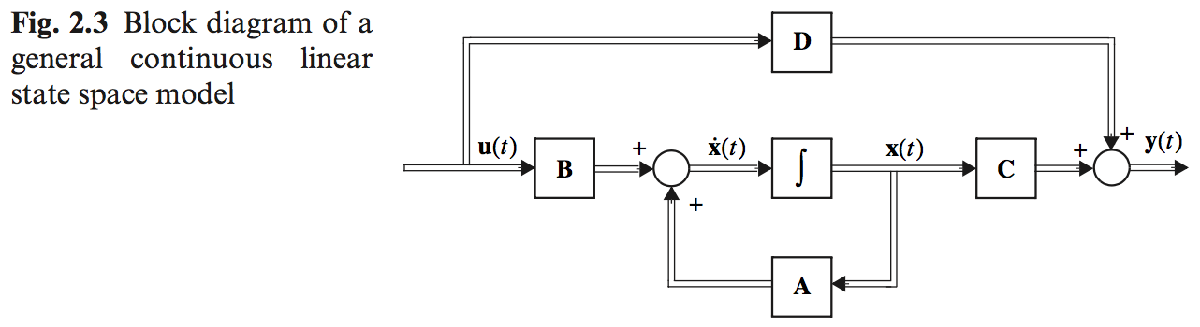

**Solution:**

**--- Simulink model **

The model of the system is entered in Simulink using the Gain-block. Remember to change the settings in the block to matrix gain as shown in Figure below. 

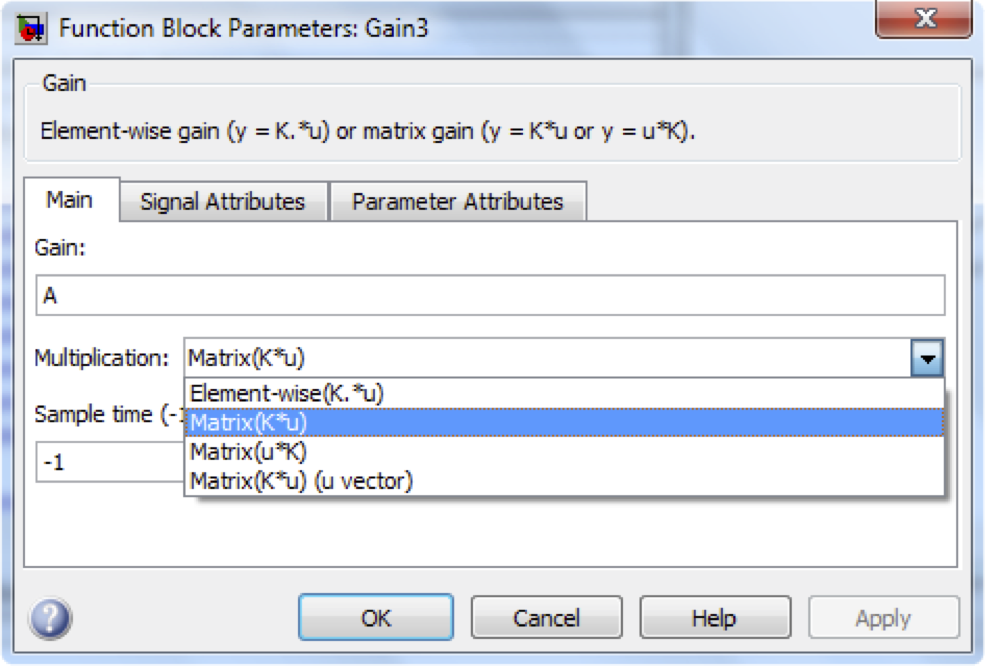

The block-diagram is entered as Fig. 2.3 in the textbook. The Simulink implementation of the block-diagram looks can be seen below

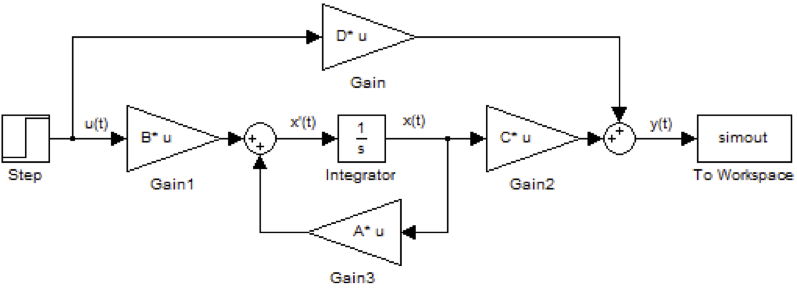

% To open simulink model, uncomment the following line and run code
% open('M10_Q3_Lat747.slx');

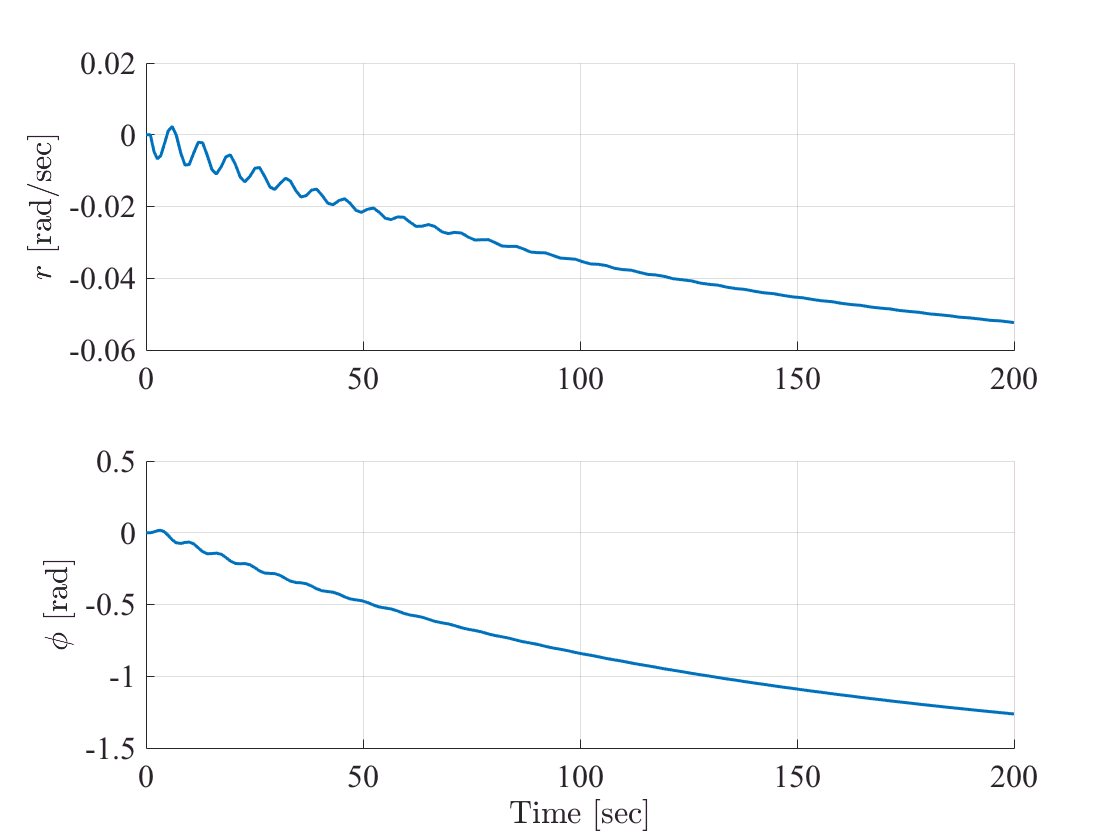

% Simulink model
u = [1*pi/180; 1*pi/180];
sim('M10_Q3_Lat747'); % Run Simulation

figure, h1 = subplot(2,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(simout.time, simout.signals.values(:,1),'LineWidth',1.5)
ylabel('$$r$$ [rad/sec]','FontName','times','FontSize',16,'Interpreter','latex');
h2 = subplot(2,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(simout.time, simout.signals.values(:,2),'LineWidth',1.5)
ylabel('$$\phi$$ [rad]','FontName','times','FontSize',16,'Interpreter','latex');
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex');

**Problem 4  **Find the 4 step responses (use the angle 1° for both inputs) and plot them in a 2 by 2 array using Matlab’s subplot-function. 

**Solution:**

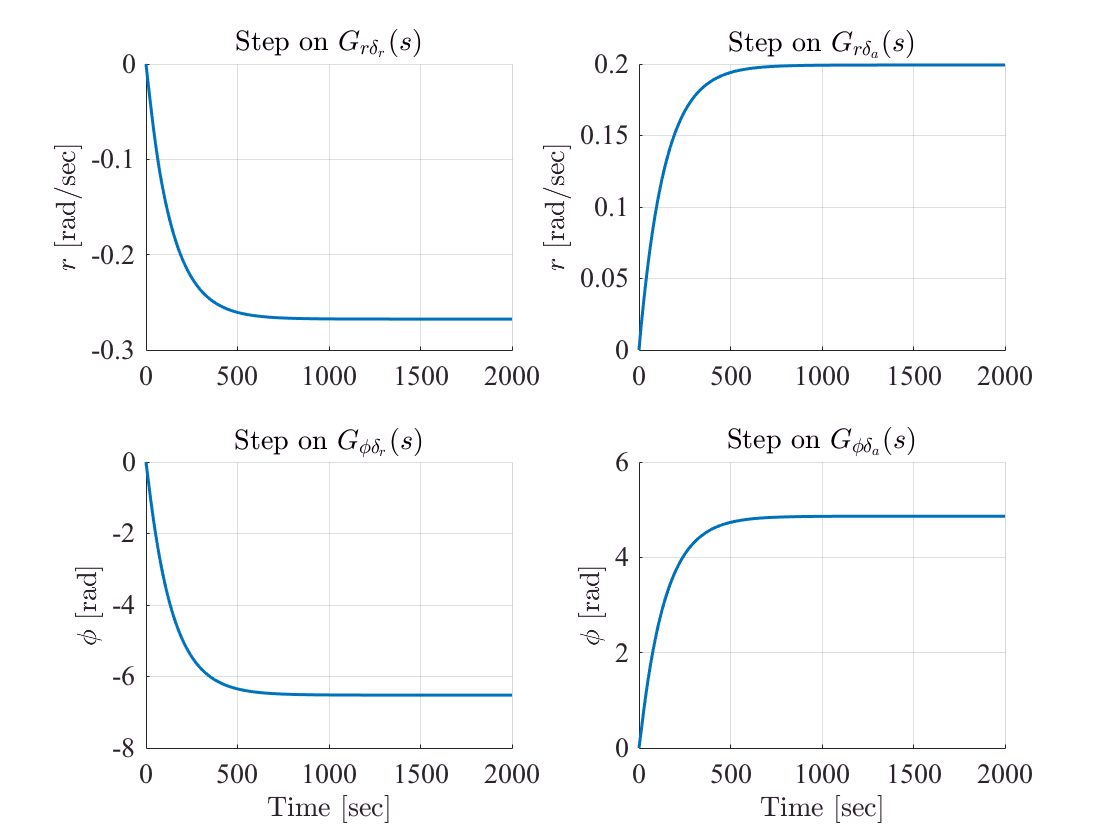

%% Q4 - Stepresponses
% Four stepresponses
tfinal = 2000;

figure, h3 = subplot(2,2,1); set(h3,'FontName','times','FontSize',14)
hold on, grid on
[y1,t1] = step(sys_tf(1,1)*2*pi/360,tfinal);
plot(t1,y1,'LineWidth',1.5)
title('Step on $$G_{r \delta_r}(s)$$','FontName','times','FontSize',14,'Interpreter','latex');
ylabel('$$r$$ [rad/sec]','FontName','times','FontSize',14,'Interpreter','latex');

h4 = subplot(2,2,3); set(h4,'FontName','times','FontSize',14)
hold on, grid on
[y2,t2] = step(sys_tf(2,1)*2*pi/360,tfinal);
plot(t2,y2,'LineWidth',1.5)
title('Step on $$G_{\phi \delta_r}(s)$$','FontName','times','FontSize',14,'Interpreter','latex');
ylabel('$$\phi$$ [rad]','FontName','times','FontSize',14,'Interpreter','latex');
xlabel('Time [sec]','FontName','times','FontSize',14,'Interpreter','latex');

h5 = subplot(2,2,2); set(h5,'FontName','times','FontSize',14)
hold on, grid on
[y3,t3] = step(sys_tf(1,2)*2*pi/360,tfinal);
plot(t3,y3,'LineWidth',1.5)
title('Step on $$G_{r \delta_a}(s)$$','FontName','times','FontSize',14,'Interpreter','latex');
ylabel('$$r$$ [rad/sec]','FontName','times','FontSize',14,'Interpreter','latex');

h6 = subplot(2,2,4); set(h6,'FontName','times','FontSize',14)
hold on, grid on
[y4,t4] = step(sys_tf(2,2)*2*pi/360,tfinal);
plot(t4,y4,'LineWidth',1.5)
title('Step on $$G_{\phi \delta_a}(s)$$','FontName','times','FontSize',14,'Interpreter','latex');
ylabel('$$\phi$$ [rad]','FontName','times','FontSize',14,'Interpreter','latex');
xlabel('Time [sec]','FontName','times','FontSize',14,'Interpreter','latex');

It was asked specifically that subplot was used, but in fact many plotting functions in matlab are capable of plotting matrix functions. A very similar plot can thus be produced simply by passing the transfer function matrix directly to step:

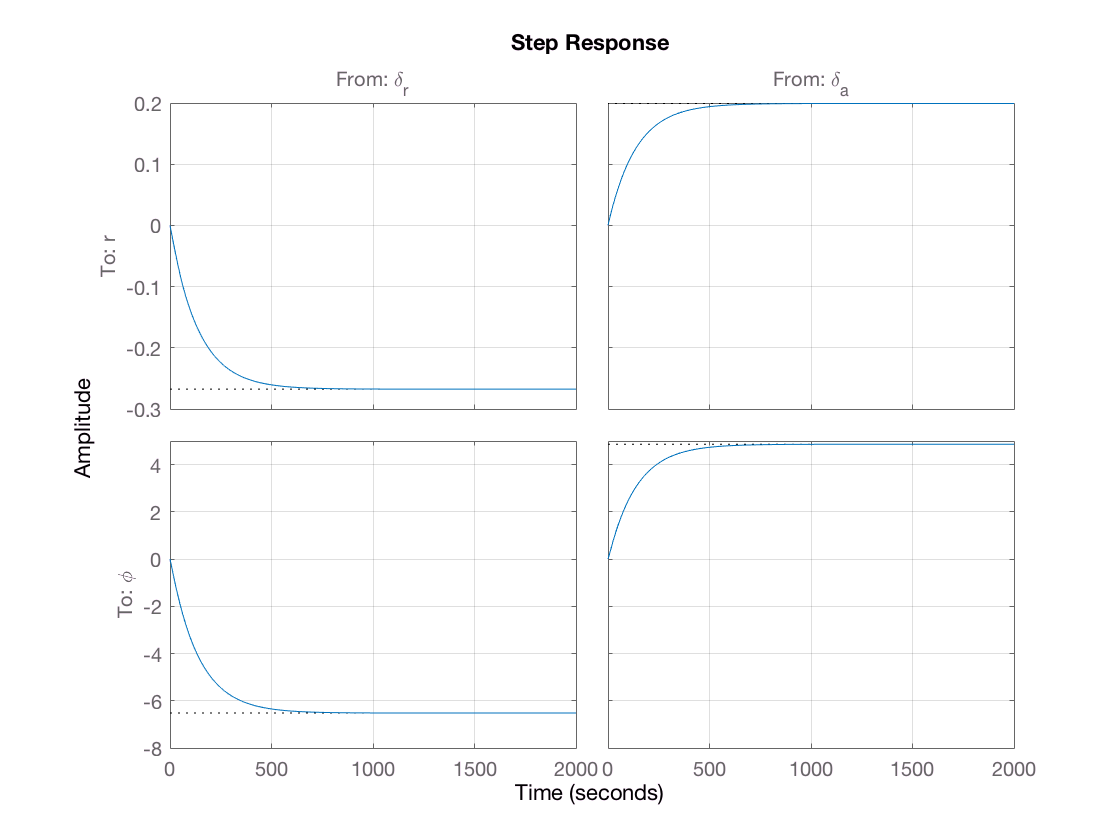

figure
step(sys_tf*2*pi/360, 2000), grid

**Problem 5**  Last, simulate the response of the linear system by using the function on the figure below at both inputs, but one at a time.

Is it possible to change the airplane’s heading by manipulating the ailerons only? 

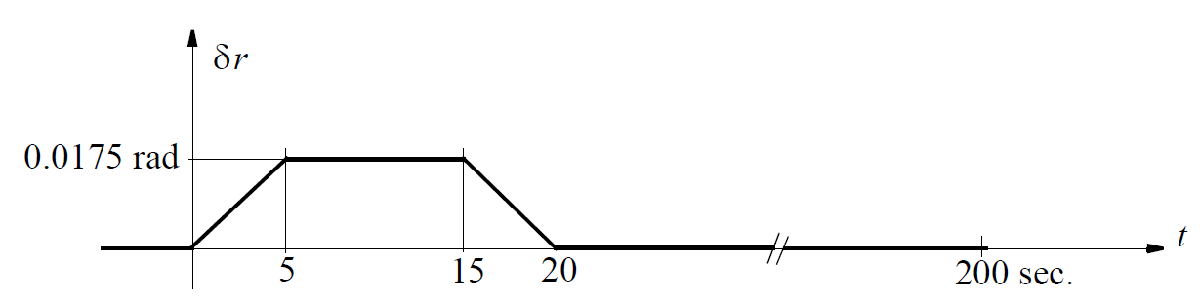	

**Solution:**

The two ramp signals for $\delta_r$ and $\delta_a$ are generated in the same way as in Group Work Module 4+5. The two signals are started at different times, as it can be seen from the `"Two input signals"` plot. When these signals are used as input for the system the response looks like the graphs in the `"Linear Simulation Results" `plot. As it can be seen from the responses, heading alteration is achievable by actuating both the rudder and the ailerons. 	 

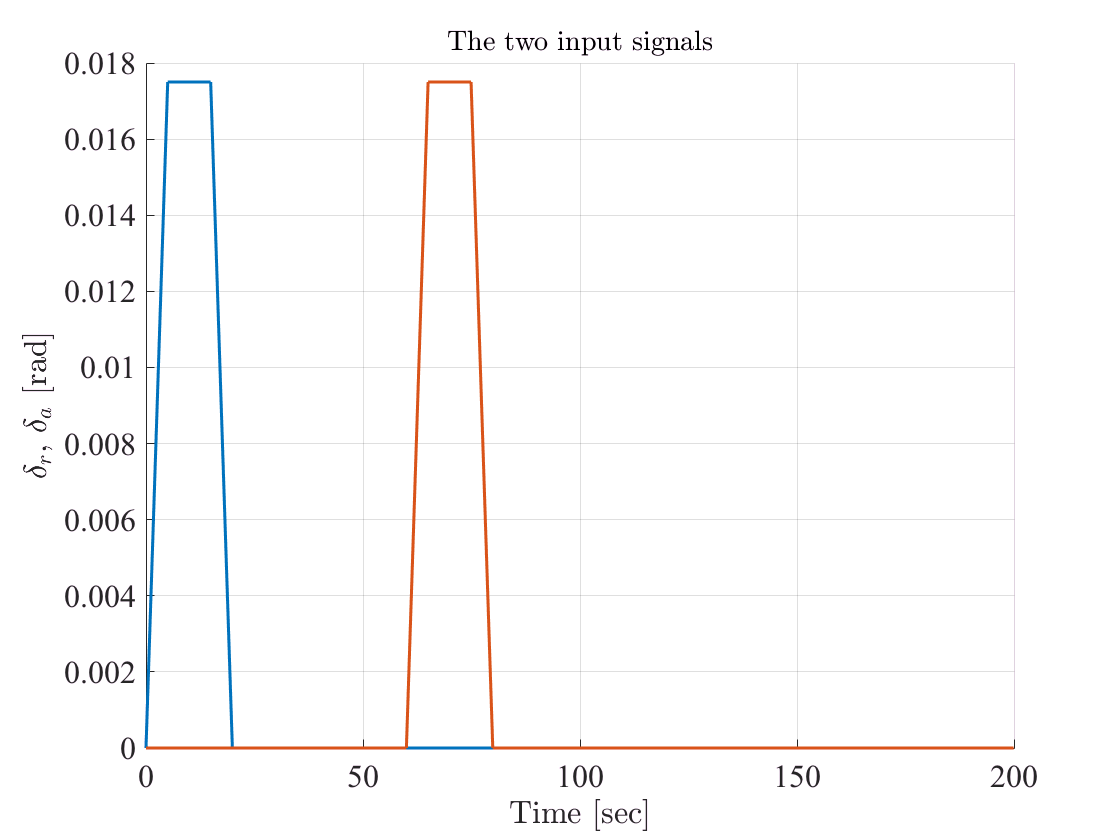

% The step functions
t = 0:.1:199.9;
bias = 600;
ut1 = (0:50) * 0.0175/50;
ut2 = ones(1,98) * 0.0175;
ut3 = (0:50) * (-0.0175/50) + 0.0175;
ut4 = zeros(1,1800);
ut5 = zeros(1,bias);
ut6 = zeros(1,1800-bias);
uttot1 = [ut1 ut2 ut3 ut4];
uttot2 = [ut5 ut1 ut2 ut3 ut6];
u = [uttot1 ; uttot2];

% Check on the steps
figure, h7 = axes; set(h7,'FontName','times','FontSize',16)
hold on, grid on
plot(t,u,'LineWidth',1.5)
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex');
ylabel('$$\delta_r, \, \delta_a$$ [rad]','FontName','times','FontSize',16,'Interpreter','latex');
title('The two input signals','FontName','times','FontSize',14,'Interpreter','latex');

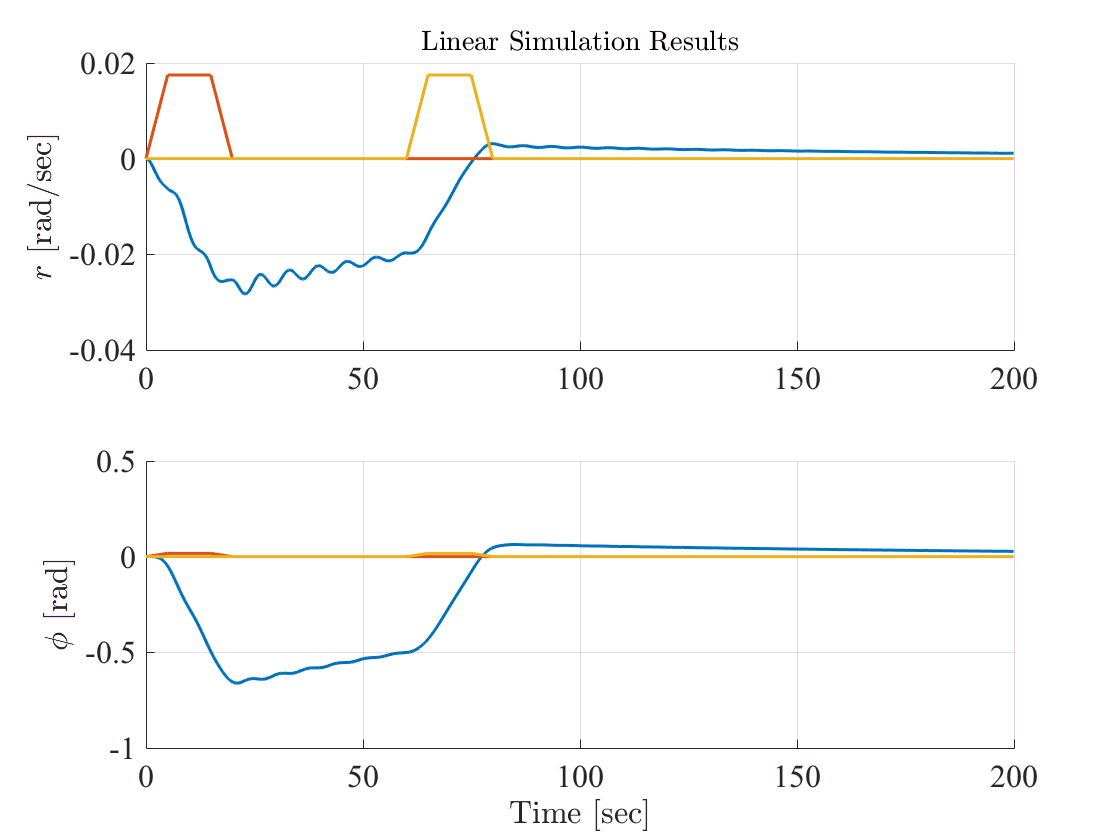


% Simulate the step
y = lsim(A,B,C,D,u,t,[0 0 0 0]');
figure, h8 = subplot(2,1,1); set(h8,'FontName','times','FontSize',16)
hold on, grid on
plot(t,y(:,1),t,u,'LineWidth',1.5)
title('Linear Simulation Results','FontName','times','FontSize',14,'Interpreter','latex');
ylabel('$$r$$ [rad/sec]','FontName','times','FontSize',16,'Interpreter','latex');
h9 = subplot(2,1,2); set(h9,'FontName','times','FontSize',16)
hold on, grid on
plot(t,y(:,2),t,u,'LineWidth',1.5)
ylabel('$$\phi$$ [rad]','FontName','times','FontSize',16,'Interpreter','latex');
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex');